# Bayes Estimation

## Motivating Example

Consider one more time the insulated stirrer experiment, introduced in the live scripts of the L7 part of the class material.

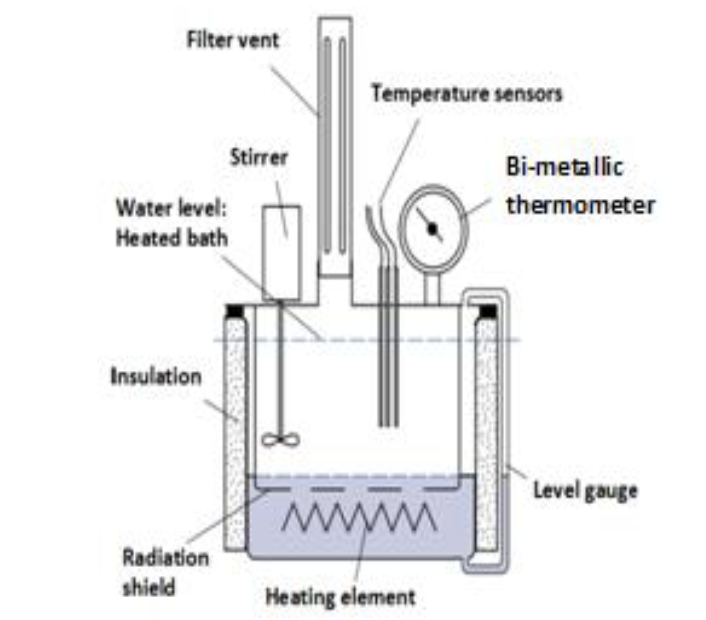

We want to measure the water temperature in an insulated stainless steel stirrer, as in Fig. 1. The water is heated with an immersion heater. We have both a thermocouple and an RTD sensor to perform the measurements. The experiment involves heating a predetermined amount of water and measuring temperature using both devices. The stirrer has good insulating capabilities, so it is assumed that the water maintains a constant temperature after the heating phase. The thermocouple and the RTD sensor provide measurements that are random variables, all with the same expected value but with different variances (and constant for each device). 

This time consider the following scenarios:

- Taking in consideration only one sensor (for example the thermocouple), collect $2N$ measurements and estimate the unkown constant water temperature, without any a priori knowledge on the effective temperature value.

- Using the same $N$ data, estimate the water temperature by means of a Bayes estimation approach, so taking into consideration not only the acquired data but also some a priori knowledge regarding the  water temperature, i.e. the expected value, the variance and the probability density function of the temperature as random variable toghether with the expected value, the variance of the noise affecting the measurments and the cross-covariance of the noise and the unknown temperature. Compare the resut with that obtained using the previous approach.

- Consider now both the sensors and acquire at every time instant a sample using each of the sensors (so collect two observatios at each time instant). Repeat such an acquisition $N$ times, collecting $2N$ data. Estimate the unknow constant temperature by measn of the weighted sampled average estimator, and compare the result with those obtained previously.

- Using the dataset just collected, using both the sensors, apply a bayesian approach to estimate the constant temperature. Take into consideration as a-priori knowledge a the expected value, the variance (using both the sensors) and the probability density function of the temperature as random variable toghether with the expected value, the variance of the noise affecting the measurments and the cross-covariance of the noise (consider both the sensor) and the unknown temperature.

clear
close all
clc


## The True Parametrization


theta_o = 47.153; % the effective value of the constant parameter to be estimated 


## The Sensor Noise Models


sigma2_v1 = 4; % the variance of the white noise stationary process describing the first sensor measurement disturbance
mu_v1 = 0; % the expected value fo the white noise acting as additive disturbance for the first sensor

sigma2_v2 = 10; % the variance of the white noise stationary process describing the 
                                        % second sensor measurement disturbance 
mu_v2 = 0; % the expected value fo the white noise acting as additive disturbance for the second sensor


## Dataset Size

In every scenario we collect $2N$ samples of the random variable $d(t) = \theta+\epsilon(t) \qquad \epsilon \sim \text{WN}\left(0,\, \lambda^2_{\epsilon} \right)$

N = 4; % we have to collect 2N data, using only one sensor (so 2N data) or both (N data using each sensor)

## A-Priori Knowledge on the Parameter $\vartheta$

As a-priori knowledge regarding the unknown parameter $\vartheta^o$ to be estimated, what we need is

- information regarding the **a-priori distribution** $p(\vartheta)$ of the parameter $\vartheta$ (as random variable) to be estimated (i.e. the a-priori probability density function, for example a gaussian probability function, or an uniform one, or something else, if appropriate)

- information about the **covariance** between the parameter $\vartheta$ acting as random variable and the white noise affecting the observations $d(t)$.

- information concerning the **joint and marginal distributions** of  the r.v. $\vartheta$ and the observations $d(\cdot)$

Let us assume that the **a-priori distribution** $p(\vartheta)$ is **gaussian**


$$p(\vartheta) = \displaystyle \frac{1}{\sqrt{2\,\pi}\,\sigma_{\vartheta}}\, \displaystyle \,e^{-\frac{\left(\vartheta-\mu_{\vartheta}\right)^2}{2\,\sigma_{\vartheta}^2}}$$


where we assume


$$\mu_{\vartheta} = 48.0 \qquad \sigma^2_{\vartheta} = 1$$


The assumptions we made allow us to state that the effective parameter $\vartheta^o$ belongs to the interval $[\mu_{\vartheta}-3\,\sigma_{\vartheta}\,,\;\mu_{\vartheta}+3\,\sigma_{\vartheta}] =[+45.0 \;,\; +51.0]$ with confidence level $99\%$ 

% the parameters of the A-PRIORI distribution of theta_o
mu_theta = 48.0;
var_theta = 1; 


Let us assume that the r.v. $\vartheta$ and the white noise $\epsilon(\cdot)$ are **independent random variables**, i.e.


$$\text{cov}\left(\vartheta\,,\; \epsilon \right) = 0$$


aPriori_cov_theta_noise = 0;

Finally, let us assume that the r.v. $\vartheta$ and the observations $d(t) = \theta^{o}+\epsilon(t) \,,\;\epsilon \sim \text{WN}\left(0,\, \lambda^2_{\epsilon} \right)$ are marginally and jointly gaussian distributed


$$\left [
\begin{array}{c}
d \\
\vartheta
\end{array}
\right ] \sim
\mathcal{G} \left (
\left [
\begin{array}{c}
d_m \\
\mu_{\vartheta}
\end{array}
\right ]
,
\left [
\begin{array}{cc}
\lambda_{dd} & \lambda_{d \vartheta} \\
\lambda_{\vartheta d} & 
\lambda_{\vartheta \vartheta}\end{array}
\right ]
\right )$$


where $d_m = \text{E}\left[d(\cdot)\right]\,,\; \lambda_{dd} = \text{var}\left[d(\cdot)\right] \;,\quad \lambda_{\vartheta d} = \text{cov}\left[\vartheta\, d\right]$.

Considering  $d(t) = \theta^{o}+\epsilon(t) \,,\;\epsilon \sim \text{WN}\left(0,\, \lambda^2_{\epsilon} \right)$, we obtain


$$d_m = \text{E}\left[d(t)\right] = \text{E}\left[\vartheta\right]+\text{E}\left[\epsilon(t)\right] = \mu_{\vartheta}+0 = \mu_{\vartheta}$$


and, since the two random variables $\vartheta$ and $\epsilon$ are independent


$$\lambda_{dd} = \text{var} \left[ d(t)\right] = \text{var} \left[ \vartheta \right] + \text{var} \left[ \epsilon(t)\right] = \sigma^2_{\vartheta} + \lambda^2_{\epsilon}$$


The effective value of $\lambda_{dd}$  depends on the different scenarios (i.e. are we using only one sensor or both the available sensors?), so that value will be computed in every scenario. The a-priori expected value of the observations is always 

d_m = mu_theta;

aand the term $\lambda_{\vartheta d}$ is (owing that $\vartheta$ and $\epsilon$ are independent random variables) 


$$\lambda_{\vartheta d} = \text{cov}\left[ \vartheta \cdot d \right] = \text{E} \big[ \left(\vartheta-\mu_{\vartheta}\right)\cdot \left(d - d_m\right) \big] = \text{E} \big[ \left(\vartheta-\mu_{\vartheta}\right)\cdot \left(\vartheta +\epsilon - \mu_{\vartheta}\right) \big]  = \text{E} \big[ \left(\vartheta-\mu_{\vartheta}\right)\cdot \left(\vartheta - \mu_{\vartheta}\right) \big]  = \sigma^2_{\vartheta}$$


## Bayesian Estimation of the Expected Value of a Random Variable - First Scenario: One Sensor Only

Let's collect the data using only the first sensor


$$d_1(t) = \vartheta+\eta_1(t) \qquad \vartheta \sim \mathcal{G}\left( \mu_{\vartheta},\,\sigma^2_{\vartheta}\right) \qquad \eta_1(\cdot) \sim \text{WN}\left(0,\,\lambda^2_1\right) \quad t=1,\,2,\,\ldots\, 2N$$


Assume that the white noise $\eta_1(\cdot)$ is 

sigma1 = sqrt(sigma2_v1); % the standard deviation of the noise
D1data = theta_o + (mu_v1 + sigma1*randn(2*N,1)); % the data - what if the sensor is biased? what if mu_v1 is non-zero?

### First Scenario: Using Only One Observation


$$d_1 = \vartheta+\eta_1 \qquad \vartheta \sim \mathcal{G}\left( \mu_{\vartheta},\,\sigma^2_{\vartheta}\right) \quad \eta_1(\cdot) \sim \text{WN}\left(0,\,\lambda^2_1\right) $$


**Using only one measurement,** how can we **estimate** the effective parameter value $\hat{\vartheta}$?

#### Without Using Any A-Priori Knowledge on the Parameter $\vartheta$

The best (and only) estimate we can compute is indeed the observation we actualy have:

d1 = D1data(1);
hat_theta_no_aPrioriK = d1 % the estimate coincides with the only value available

hat_theta_no_aPrioriK =   50.986187141923800


Moreover, the variance of such a "raw" estimate is the a-priori variance of the observation $d$


$$\lambda_{dd} = \text{var} \left[ d\right] = \text{var} \left[ \vartheta \right] + \text{var} \left[ \eta\right] = \sigma^2_{\vartheta} + \lambda^2_{1}$$


var_hat_theta_no_aPrioriK = sigma2_v1 + var_theta

var_hat_theta_no_aPrioriK =      5


#### Using the A-Priori Knowledge: Bayes Estimation

Now let us apply the bayesian approach to estimate $\vartheta^o$ using the unique observation we collected so far, toghether with the a-priori knoledge we have regarding the parameter $\vartheta$

lambda_dd = var_theta + sigma2_v1; % the avariance of the observations

lambda_theta_d = var_theta;
lambda_d_theta = lambda_theta_d'; 

Lambda_theta_d_MAT = [lambda_dd       , lambda_d_theta; ...
                       lambda_theta_d ,  var_theta         ]; % the joint variance matrix

The a-posteriori estimate $\hat{\vartheta$ is


$$\left \{
\begin{array}{l}
\hat \vartheta = \vartheta_m+
{\lambda_{\vartheta d}} \, {\lambda_{dd}}^{-1}
 \, (d-d_m) \\
{\rm var} \, (\vartheta - \hat \vartheta)= 
\lambda_{\vartheta \vartheta}-
{\lambda_{\vartheta d}} \, {\lambda_{dd}}^{-1}
{\lambda_{d \vartheta}}
\end{array}
\right .$$


hat_thetaBayes = mu_theta + (lambda_theta_d/lambda_dd)*(d1-d_m)

hat_thetaBayes =   48.597237428384759


var_hat_thetaBayes = var_theta - (lambda_theta_d/lambda_dd)*lambda_d_theta

var_hat_thetaBayes =    0.800000000000000


#### Comparing the Results

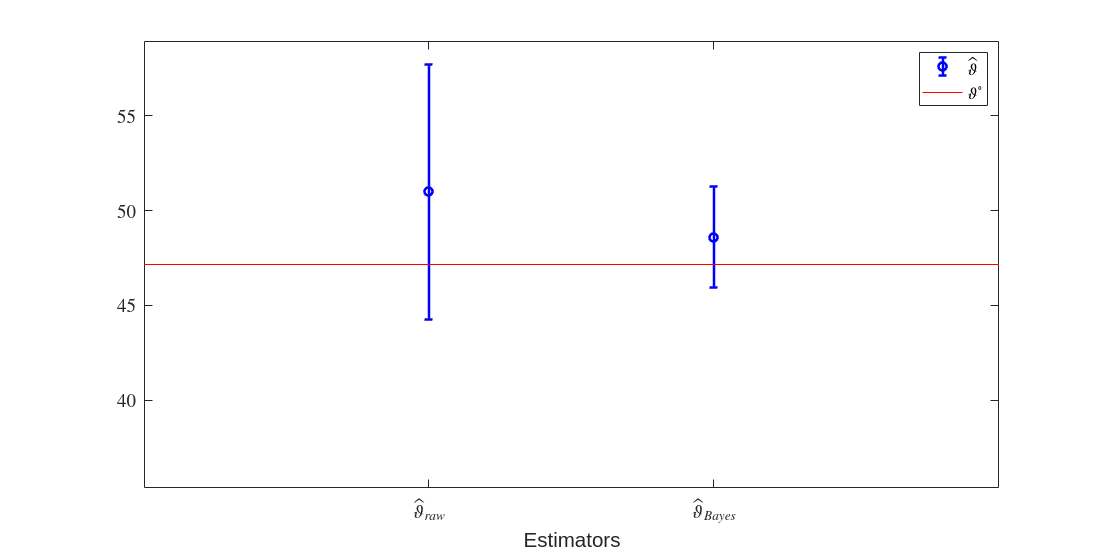

a =3;    % in order to build the confidence interval, we will use +/- a*std() as extrema


figure('Units','normalized','Position',[0.1, 0.1,0.90,0.80]);

hat_theta = [hat_theta_no_aPrioriK ; hat_thetaBayes];     % the estimated mean value
hat_sigma = [sqrt(var_hat_theta_no_aPrioriK); sqrt(var_hat_thetaBayes)]; 
% the std. dev. of the estimated mean value

R = numel(hat_theta);

errorbar(hat_theta,a*hat_sigma,'ob','linewidth',2)
hold on
plot((0:R+1),theta_o*ones(1,R+2),'r')
hold off
axis([0 R+1 0.75*theta_o 1.25*theta_o])
legend('$\hat\vartheta$','$\vartheta^{\circ}$','Interpreter','latex')
xlabel('Estimators')
ax = gca;
ax.XTick = [1 2];
ax.XTickLabel = {'$\hat{\vartheta}_{raw}$','$\hat{\vartheta}_{Bayes}$'};
ax.TickLabelInterpreter = "latex";
%title(['Sample mean with ',num2str(a),' sigma interval'])
set(gca, 'Fontsize', 14);

### Second Scenario: Using More than One Observation

This time we collect $2 N$ observations


$$d_1(t) = \vartheta^{o}+\eta_1(t) \qquad \eta_1(\cdot) \sim \text{WN}\left(0,\,\lambda^2_1\right) \quad t=1,\,2,\,\ldots\, 2N$$


How can we **estimate** the effective parameter value $\hat{\vartheta}$?

#### Without Using Any A-Priori Knowledge on the Parameter $\vartheta
$

The best estimate we can compute is indeed the sampled average of the observations:

hat_theta_2N_no_aPrioriK = mean(D1data) 

hat_theta_2N_no_aPrioriK =   47.169896317869224


Moreover, the variance of such a nestimate is the sampled variance of the measurements:

var_hat_theta_2N_no_aPrioriK = var(D1data)

var_hat_theta_2N_no_aPrioriK =    6.844000066244400


#### Using the A-Priori Knowledge: Bayes Estimation

Now let us apply the bayesian approach to estimate $\vartheta^o$ using the $2 N$ observation we collected so far, toghether with the a-priori knoledge we have regarding the parameter $\vartheta$


$$\Lambda_{dd} = \left[ \begin{array}{ccccc}
\text{var}[d(1)] & \text{cov}\left[d(1)\cdot d(2)\right] & \text{cov}\left[d(1)\cdot d(3)\right] & \cdots &\text{cov}\left[d(1)\cdot d(2N)\right] \\
\text{cov}\left[d(2)\cdot d(1)\right] & \text{var}[d(2)]  & \text{cov}\left[d(2)\cdot d(3)\right] & \cdots &\text{cov}\left[d(2)\cdot d(2N)\right] \\
\text{cov}\left[d(3)\cdot d(1)\right] & \text{cov}\left[d(3)\cdot d(2)\right] & \text{var}[d(3)]  & \cdots & \text{cov}\left[d(3)\cdot d(2N)\right] \\
                                                      &                                                      & \ddots              &                                                                       \\
\text{cov}\left[d(2N)\cdot d(1)\right] & \text{cov}\left[d(2N)\cdot d(2)\right] & \cdots          & \text{cov}\left[d(2N)\cdot d(2N-1)\right] &  \text{var}[d(2N)] 
\end{array} \right]$$


where


$$ \text{var} \left[ d(i)\right] = \text{var} \left[ \vartheta \right] + \text{var} \left[ \eta(i)\right] = \sigma^2_{\vartheta} + \lambda^2_{\eta} \qquad i=1,\,2,\,\ldots 2N$$



$$ \text{cov} \left[ d(i) \cdot d(j) \right] = \text{E} \big[ \left(d(i)-d_m\right)\cdot \left(d(j)-d_m\right) \big] = 
\text{E} \big[ \left( \vartheta +\eta(i) - \mu_{\vartheta} \right) \cdot \left( \vartheta +\eta(j) - \mu_{\vartheta} \right) \big] = \text{var}\left[ \vartheta \right] + \text{E} \left[ \eta(i) \cdot \eta(j) \right] = \sigma^2_{\vartheta} \quad \forall i \ne j$$


Lambda_dd = ones(2*N).*var_theta + diag(ones(2*N,1).* (sigma2_v1)); 
% the variance of the observations is now a square matrix, of order 2N
% the observations are independent of each other and each has the same variance



$$\Lambda_{\vartheta d} = \big[ \begin{array}{ccccc}
\text{cov}\left[\vartheta \cdot d(1) \right] & \text{cov}\left[\vartheta \cdot d(2) \right] & \text{cov}\left[\vartheta \cdot d(3) \right] & \cdots & \text{cov}\left[\vartheta \cdot d(2N) \right] 
\end{array} \big] \qquad \Lambda_{d \vartheta} = \Big[ \Lambda_{\vartheta d} \Big]^{\top}$$


where


$$ \text{cov}\left[ \vartheta \cdot d(i) \right] = \text{E} \big[ \left(\vartheta-\mu_{\vartheta}\right)\cdot \left(d(i) - d_m\right) \big] = \text{E} \big[ \left(\vartheta-\mu_{\vartheta}\right)\cdot \left(\vartheta +\eta(i) - \mu_{\vartheta}\right) \big]  = \text{E} \big[ \left(\vartheta-\mu_{\vartheta}\right)\cdot \left(\vartheta - \mu_{\vartheta}\right) \big]  = \sigma^2_{\vartheta} \quad \forall i$$



Lambda_theta_d = var_theta .* ones(1, 2*N); % a row matrix
Lambda_d_theta = Lambda_theta_d'; % a column matrix

Lambda_theta_d_MAT = [Lambda_dd       , Lambda_d_theta; ...
                       Lambda_theta_d ,  var_theta         ]; % the joint variance matrix: a square matrix of order 2N+1

The a-posteriori estimate $\hat{\vartheta$ is


$$\left \{
\begin{array}{l}
\hat \vartheta = \vartheta_m+
{\Lambda_{\vartheta d}} \, {\Lambda_{dd}}^{-1}
 \, (d-d_m) \\
{\rm var} \, (\vartheta - \hat \vartheta)= 
\Lambda_{\vartheta \vartheta}-
{\Lambda_{\vartheta d}} \, {\Lambda_{dd}}^{-1}
{\Lambda_{d \vartheta}}
\end{array}
\right .$$


hat_theta2N_Bayes = mu_theta + Lambda_theta_d * inv(Lambda_dd)*(D1data-d_m)

hat_theta2N_Bayes =   47.446597545246149


var_hat_theta2N_Bayes = var_theta - Lambda_theta_d * (Lambda_dd \ Lambda_d_theta)

var_hat_theta2N_Bayes =    0.333333333333333


#### Comparing the Results

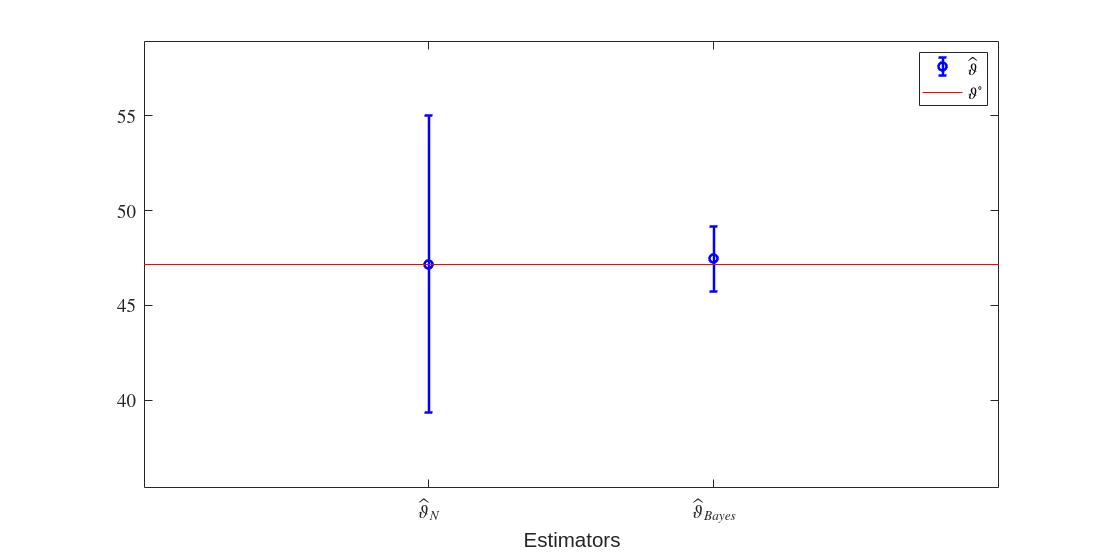

figure('Units','normalized','Position',[0.1, 0.1,0.90,0.80]);

hat_theta = [hat_theta_2N_no_aPrioriK ; hat_theta2N_Bayes];     % the estimated mean value
hat_sigma = [sqrt(var_hat_theta_2N_no_aPrioriK); sqrt(var_hat_theta2N_Bayes)]; 
% the std. dev. of the estimated mean value

R = numel(hat_theta);

errorbar(hat_theta,a*hat_sigma,'ob','linewidth',2)
hold on
plot((0:R+1),theta_o*ones(1,R+2),'r')
hold off
axis([0 R+1 0.75*theta_o 1.25*theta_o])
legend('$\hat\vartheta$','$\vartheta^{\circ}$','Interpreter','latex')
xlabel('Estimators')
ax = gca;
ax.XTick = [1 2];
ax.XTickLabel = {'$\hat{\vartheta}_{N}$','$\hat{\vartheta}_{Bayes}$'};
ax.TickLabelInterpreter = "latex";
%title(['Sample mean with ',num2str(a),' sigma interval'])
set(gca, 'Fontsize', 14);

## Bayesian Estimation of the Expected Value of a Random Variable - Second Scenario: Using Both Sensors 

Suppose now to employ both the sensors and **to acquire the measurements using each sensor,** having in total two sets of observations:


$$\left\{
\begin{array}{rcl}
d_1(t) &=& \vartheta+\eta_1(t) \qquad \eta_1(\cdot) \sim \text{WN}\left(0,\,\lambda^2_1\right) \\
d_2(t) &=& \vartheta+\eta_2(t) \qquad \eta_2(\cdot) \sim \text{WN}\left(0,\,\lambda^2_2\right) 
\end{array}
\right. \qquad t=1,\,2,\,\ldots N$$


Collect the data using the first and the second sensor:

sigma1 = sqrt(sigma2_v1); % the standard deviation of the noise for the 1st device
D1data = theta_o + (mu_v1 + sigma1*randn(N,1)); % the data - what if the sensor is biased? what if mu_v1 is non-zero?

sigma2 = sqrt(sigma2_v2); % the standard deviation of the noise for the 2nd sensor
D2data = theta_o + (mu_v2 + sigma2*randn(N,1)); % the data - what if the sensor is biased? what if mu_v1 is non-zero?

### First Scenario: Using Only Two Observation

Suppose we acquire a measurement for each sensor, using them simultaneously


$$d_1 = \vartheta+\eta_1 \qquad \vartheta \sim \mathcal{G}\left( \mu_{\vartheta},\,\sigma^2_{\vartheta}\right) \quad \eta_1(\cdot) \sim \text{WN}\left(0,\,\lambda^2_1\right) $$



$$d_2 = \vartheta+\eta_2 \qquad \vartheta \sim \mathcal{G}\left( \mu_{\vartheta},\,\sigma^2_{\vartheta}\right) \quad \eta_2(\cdot) \sim \text{WN}\left(0,\,\lambda^2_2\right) $$


**Using only these measurements, ** how can we **estimate** the effective parameter value $\hat{\vartheta}$?

#### Without Using Any A-Priori Knowledge on the Parameter $\vartheta$

The best  estimate we can compute is indeed the weighted sampled average of the observations we actualy have:

d1 = D1data(1);
d2 = D2data(1);
% the observations d1 and d2

The weighted sampled-average estimator is


$$\hat{\vartheta}_{N} = \sum_{i=1}^{N}\, \alpha(i) \, d(i) \qquad \sum_{i=1}^{N} \, \alpha(i) = 1 $$


where


$$\alpha(i) = \frac{1}{\text{var} \left[ d(i) \right]}  \displaystyle \cdot  \frac{1}{\displaystyle \sum_{i=1}^{N} \displaystyle \frac{1}{\text{var} \left[ d(i) \right]}} $$


Thus

alpha1 = (1/sigma2_v1); % the weights for d1
alpha2 = (1/sigma2_v2); % the weights for d2

hat_theta_W_no_aPrioriK = ((alpha1 .* d1) + (alpha2 .* d2)) / ((1/sigma2_v1) + (1/sigma2_v2))

hat_theta_W_no_aPrioriK =   49.045213592164032


The variance of the estimate takes the expression


$$\text{var} \left( \hat{\vartheta}_{N} \right) = \displaystyle  \frac{1}{\sum_{i=1}^{N} \frac{1}{\text{var} \left[ d(i) \right]}}$$


var_hat_theta_W_no_aPrioriK = 1/((1/sigma2_v1) + (1/sigma2_v2))

var_hat_theta_W_no_aPrioriK =    2.857142857142857


#### Using the A-Priori Knowledge: Bayes Estimation

Now let us apply the bayesian approach to estimate $\vartheta^o$ using the observations $d_1$ and $d_2$, toghether with the a-priori knoledge we have regarding the parameter $\vartheta$


$$\Lambda_{dd} = \left[ \begin{array}{cc}
\text{var}[d_1] & \text{cov}\left[d_1\cdot d_2\right] \\
\text{cov}\left[d_2\cdot d_1\right] & \text{var}[d_2]   
\end{array} \right]$$


where


$$ \text{var} \left[ d_i\right] = \text{var} \left[ \vartheta \right] + \text{var} \left[ \eta_i\right] = \sigma^2_{\vartheta} + \lambda^2_{i} \qquad i=1,\,2$$



$$ \text{cov} \left[ d_1 \cdot d_2 \right] = \text{E} \big[ \left(d_1-d_m\right)\cdot \left(d_2-d_m\right) \big] = 
\text{E} \big[ \left( \vartheta +\eta_1 - \mu_{\vartheta} \right) \cdot \left( \vartheta +\eta_2 - \mu_{\vartheta} \right) \big] = \text{var}\left[ \vartheta \right] + \text{E} \left[ \eta_1 \cdot \eta_2\right] = \sigma^2_{\vartheta}$$


Lambda_dd = [var_theta + sigma2_v1,  var_theta;...
              var_theta,    var_theta + sigma2_v2]; % the covariance matrix 



$$\Lambda_{\vartheta d} = \big[ \begin{array}{cc}
\text{cov}\left[\vartheta \cdot d_1 \right] & \text{cov}\left[\vartheta \cdot d_2 \right] 
\end{array} \big] \qquad \Lambda_{d \vartheta} = \Big[ \Lambda_{\vartheta d} \Big]^{\top}$$


where


$$ \text{cov}\left[ \vartheta \cdot d_i \right] = \text{E} \big[ \left(\vartheta-\mu_{\vartheta}\right)\cdot \left(d_i - d_m\right) \big] = \text{E} \big[ \left(\vartheta-\mu_{\vartheta}\right)\cdot \left(\vartheta +\eta_i - \mu_{\vartheta}\right) \big]  = \text{E} \big[ \left(\vartheta-\mu_{\vartheta}\right)\cdot \left(\vartheta - \mu_{\vartheta}\right) \big]  = \sigma^2_{\vartheta} \quad \forall i$$



Lambda_theta_d = [var_theta, var_theta];
Lambda_d_theta = Lambda_theta_d'; 

Lambda_theta_d_MAT = [lambda_dd       , lambda_d_theta; ...
                       lambda_theta_d ,  var_theta         ]; % the joint covariance matrix

The a-posteriori estimate $\hat{\vartheta$ is


$$\left \{
\begin{array}{l}
\hat \vartheta = \vartheta_m+
{\Lambda_{\vartheta d}} \, {\Lambda_{dd}}^{-1}
 \, (d-d_m) \\
{\rm var} \, (\vartheta - \hat \vartheta)= 
\Lambda_{\vartheta \vartheta}-
{\Lambda_{\vartheta d}} \, {\Lambda_{dd}}^{-1}
{\Lambda_{d \vartheta}}
\end{array}
\right .$$


D = [d1; d2]; % the vector containing the obervations
hat_thetaW_Bayes = mu_theta + Lambda_theta_d * (Lambda_dd \(D-d_m*ones(size(D))))

hat_thetaW_Bayes =   48.270981301672158


% the estimate

var_hat_thetaW_Bayes = var_theta - Lambda_theta_d * (Lambda_dd\Lambda_d_theta)

var_hat_thetaW_Bayes =    0.740740740740741


% the variance 

#### Comparing the Results

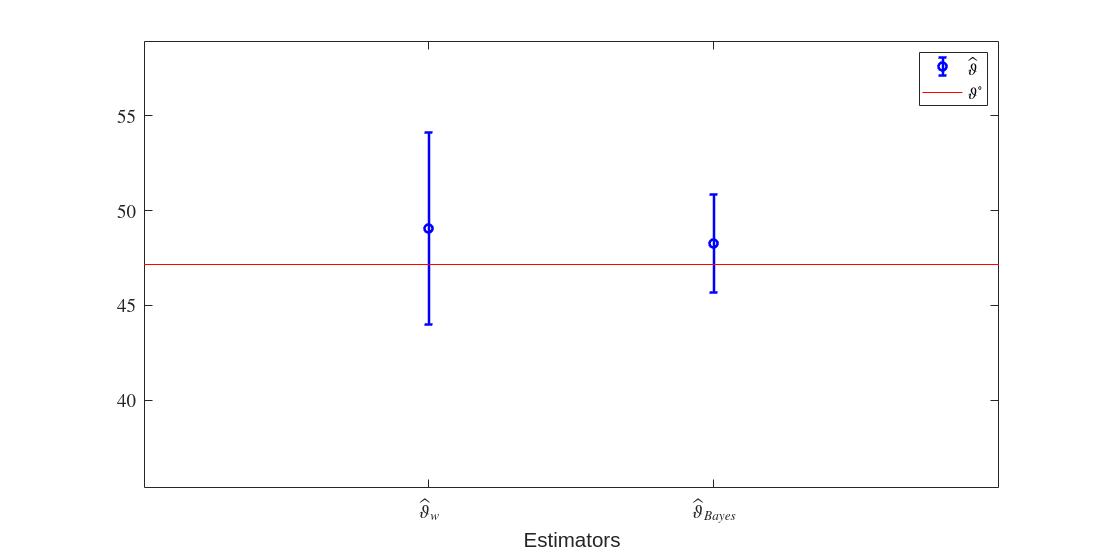

figure('Units','normalized','Position',[0.1, 0.1,0.90,0.80]);

hat_theta = [hat_theta_W_no_aPrioriK ; hat_thetaW_Bayes];     % the estimated mean value
hat_sigma = [sqrt(var_hat_theta_W_no_aPrioriK); sqrt(var_hat_thetaW_Bayes)]; 
% the std. dev. of the estimated mean value

R = numel(hat_theta);

errorbar(hat_theta,a*hat_sigma,'ob','linewidth',2)
hold on
plot((0:R+1),theta_o*ones(1,R+2),'r')
hold off
axis([0 R+1 0.75*theta_o 1.25*theta_o])
legend('$\hat\vartheta$','$\vartheta^{\circ}$','Interpreter','latex')
xlabel('Estimators')
ax = gca;
ax.XTick = [1 2];
ax.XTickLabel = {'$\hat{\vartheta}_{w}$','$\hat{\vartheta}_{Bayes}$'};
ax.TickLabelInterpreter = "latex";
%title(['Sample mean with ',num2str(a),' sigma interval'])
set(gca, 'Fontsize', 14);

### Second Scenario: Using All the Observations

Suppose we acquire $N$ measurement for each sensor, using them simultaneously


$$d_1(t) = \vartheta+\eta_1(t) \qquad \vartheta \sim \mathcal{G}\left( \mu_{\vartheta},\,\sigma^2_{\vartheta}\right) \quad \eta_1(\cdot) \sim \text{WN}\left(0,\,\lambda^2_1\right) \qquad t=1,\,2,\,\ldots N$$



$$d_2(t) = \vartheta+\eta_2(t) \qquad \vartheta \sim \mathcal{G}\left( \mu_{\vartheta},\,\sigma^2_{\vartheta}\right) \quad \eta_2(\cdot) \sim \text{WN}\left(0,\,\lambda^2_2\right) \qquad t=1,\,2,\,\ldots N$$


How can we **estimate** the effective parameter value $\hat{\vartheta}$?

#### Without Using Any A-Priori Knowledge on the Parameter $\vartheta$

The best estimate we can compute is the weighted sampled average of the observations:

When $d(i) \in D_i$


$$\forall j: d(j) \in D_i\,,\quad \text{var}\big(d(j)\big) = \sigma^2_{v_i} \quad \Longrightarrow \quad \alpha(j) = \frac{1}{\text{var} \left[ d(j) \right]}  \displaystyle \cdot  \frac{1}{\displaystyle \sum_{i=1}^{N} \displaystyle \frac{1}{\text{var} \left[ d(i) \right]}} = \frac{1}{\sigma^2_{v_1}} \cdot  \frac{1}{\displaystyle \frac{N_1}{\sigma^2_{v_1}}+\frac{N_2}{\sigma^2_{v_2}}$$


Thus


$$\hat \vartheta_{WN}=\frac{\sum_{p=1}^{N_1}\frac{d_{1,p}}{\sigma_{v_1}^2}+\sum_{q=1}^{N_2}\frac{d_{2,q}}{\sigma_{v_2}^2}}{\frac{N_1}{\sigma_{v_1}^2}+\frac{N_2}{\sigma_{v_2}^2}}.$$
        
$$\sigma^2_{\hat{\vartheta}_{W N}} =
\Big(\frac{N_1}{\sigma^2_{v_1}}+\frac{N_2}{\sigma^2_{v_2}}  \Big)^{-1}
$$


whereas


$$\hat{\vartheta}_{N}= \displaystyle \frac{1}{N}\, \sum_{i=1}^{N} d(i) $$
        
$$\text{var} \left( \hat{\vartheta}_{N} \right) = \displaystyle \frac{1}{N^2} \sum_{i=1}^{N}\,\text{var}\big(d(i)\big) = 
\frac{N_1\sigma_{v_1}^2+N_2\sigma_{v_2}^2}{N^2}$$


alpha1 = (1/sigma2_v1)*ones(N,1); % the weights for the D1 dataset
alpha2 = (1/sigma2_v2)*ones(N,1); % the weights for the D2 dataset

hat_theta_W_N__no_aPrioriK = (sum(alpha1 .* D1data) + sum(alpha2 .* D2data)) / ((N/sigma2_v1) + (N/sigma2_v2))

hat_theta_W_N__no_aPrioriK =   46.570072646294989


Moreover, the variance of such a nestimate is the sampled variance of the measurements:

var_hat_theta_W_N__no_aPrioriK = 1/((N/sigma2_v1) + (N/sigma2_v2))

var_hat_theta_W_N__no_aPrioriK =    0.714285714285714


#### Using the A-Priori Knowledge: Bayes Estimation

Now let us apply the bayesian approach to estimate $\vartheta^o$ using the $2 N$ observation we collected so far, toghether with the a-priori knoledge we have regarding the parameter $\vartheta$


$$\Lambda_{dd} = \left[ \begin{array}{cc}
\Lambda_{D_1 D_1} & \Lambda_{D_1 D_2} \\
\Lambda_{D_2 D_1} & \Lambda_{D_2 D_2}
\end{array} \right]$$


where


$$\Lambda_{D_i D_i} = \left[ \begin{array}{ccccc}
\text{var}[d_i(1)] & \text{cov}\left[d_i(1)\cdot d_i(2)\right] & \text{cov}\left[d_i(1)\cdot d_i(3)\right] & \cdots &\text{cov}\left[d_i(1)\cdot d_i(N)\right] \\
\text{cov}\left[d_i(2)\cdot d_i(1)\right] & \text{var}[d_i(2)]  & \text{cov}\left[d_i(2)\cdot d_i(3)\right] & \cdots &\text{cov}\left[d_i(2)\cdot d_i(N)\right] \\
\text{cov}\left[d_i(3)\cdot d_i(1)\right] & \text{cov}\left[d_i(3)\cdot d_i(2)\right] & \text{var}[d_i(3)]  & \cdots & \text{cov}\left[d_i(3)\cdot d_i(N)\right] \\
                                                      &                                                      & \ddots              &                                                                       \\
\text{cov}\left[d_i(N)\cdot d_i(1)\right] & \text{cov}\left[d_i(N)\cdot d_i(2)\right] & \cdots          & \text{cov}\left[d_i(N)\cdot d_i(N-1)\right] &  \text{var}[d_i(N)] 
\end{array} \right] \qquad i=1,\,2$$


and


$$ \text{var} \left[ d_i(t)\right] = \text{var} \left[ \vartheta \right] + \text{var} \left[ \eta_i(t)\right] = \sigma^2_{\vartheta} + \lambda^2_{i} \qquad i=1,\,2 \quad t=1,\,2,\,\ldots N$$



$$ \text{cov} \left[ d_k(i) \cdot d_k(j) \right] = \text{E} \big[ \left(d_k(i)-d_m\right)\cdot \left(d_k(j)-d_m\right) \big] = 
\text{E} \big[ \left( \vartheta +\eta_k(i) - \mu_{\vartheta} \right) \cdot \left( \vartheta +\eta_k(j) - \mu_{\vartheta} \right) \big] = \text{var}\left[ \vartheta \right] + \text{E} \left[ \eta_k(i) \cdot \eta_k(j) \right] = \sigma^2_{\vartheta} \quad \forall i \ne j \quad k=1,\,2$$


Moreover


$$\Lambda_{D_1 D_2} = \text{E} \left\{
 \left[ \begin{array}{c} 
d_1(1) -d_m \\
d_1(2)-d_m\\
\vdots \\
d_1(N)-d_m
\end{array} \right] \cdot 
\big[ \begin{array}{ccccc}
d_2(1)-d_m & d_2(2)-d_m & d_2(3)-d_m & \cdots & d_2(N)-d_m
\end{array} \big]^{\top} \right\} \qquad \Lambda_{D_2 D_1} = \big[ \Lambda_{D_1 D_2}  \big]^{\top}$$


Lambda_dd_1 = ones(N).*var_theta + diag(ones(N,1).* (sigma2_v1)); 
Lambda_dd_2 = ones(N).*var_theta + diag(ones(N,1).* (sigma2_v2)); 

Lambda_d1d2 = ones(N).*var_theta; Lambda_d2d1 = Lambda_d1d2';

Lambda_DD = [Lambda_dd_1, Lambda_d1d2; ...
             Lambda_d2d1, Lambda_dd_2];

% the variance of the observations is now a square matrix, of order 2N
% the observations are independent of each other and each has the same variance



$$\Lambda_{\vartheta D} = \Big[ \begin{array}{cccccccc}
\text{cov}\left[\vartheta \cdot d_1(1) \right] & \text{cov}\left[\vartheta \cdot d_1(2) \right] &  \cdots & \text{cov}\left[\vartheta \cdot d_1(N) \right] & 
\text{cov}\left[\vartheta \cdot d_2(1) \right] & \text{cov}\left[\vartheta \cdot d_2(2) \right] &  \cdots & \text{cov}\left[\vartheta \cdot d_2(N) \right] 
\end{array} \Big] \qquad \Lambda_{d \vartheta} = \Big[ \Lambda_{\vartheta d} \Big]^{\top}$$


where


$$ \text{cov}\left[ \vartheta \cdot d_k(i) \right] = \text{E} \big[ \left(\vartheta-\mu_{\vartheta}\right)\cdot \left(d_k(i) - d_m\right) \big] = \text{E} \big[ \left(\vartheta-\mu_{\vartheta}\right)\cdot \left(\vartheta +\eta_k(i) - \mu_{\vartheta}\right) \big]  = \text{E} \big[ \left(\vartheta-\mu_{\vartheta}\right)\cdot \left(\vartheta - \mu_{\vartheta}\right) \big]  = \sigma^2_{\vartheta} \quad \forall i \quad k=1,\,2$$


Lambda_theta_D = [var_theta .* ones(1, N) var_theta .* ones(1, N)]; % a row matrix
Lambda_D_theta = Lambda_theta_D'; % a column matrix

Lambda_theta_D_MAT = [Lambda_DD       , Lambda_D_theta; ...
                       Lambda_theta_D ,  var_theta         ]; % the joint variance matrix: a square matrix of order 2N+1

The a-posteriori estimate $\hat{\vartheta$ is


$$\left \{
\begin{array}{l}
\hat \vartheta = \vartheta_m+
{\Lambda_{\vartheta D}} \, {\Lambda_{DD}}^{-1}
 \, (D-D_m) \\
{\rm var} \, (\vartheta - \hat \vartheta)= 
\Lambda_{\vartheta \vartheta}-
{\Lambda_{\vartheta D}} \, {\Lambda_{DD}}^{-1}
{\Lambda_{D \vartheta}}
\end{array}
\right .$$


D_data = [D1data; D2data];

hat_theta_W_2N_Bayes = mu_theta + Lambda_theta_D * inv(Lambda_DD)*(D_data-d_m)

hat_theta_W_2N_Bayes =   47.165875710338739


var_hat_theta_W_2N_Bayes = var_theta - Lambda_theta_D * (Lambda_DD \ Lambda_D_theta)

var_hat_theta_W_2N_Bayes =    0.416666666666667


#### Comparing the Results

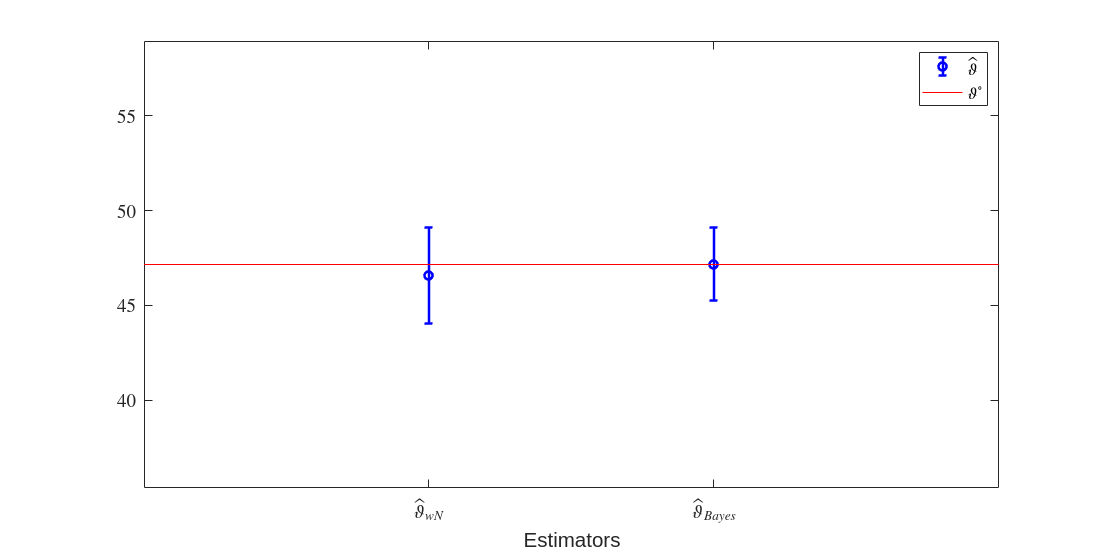

figure('Units','normalized','Position',[0.1, 0.1,0.90,0.80]);

hat_theta = [hat_theta_W_N__no_aPrioriK ; hat_theta_W_2N_Bayes];     % the estimated mean value
hat_sigma = [sqrt(var_hat_theta_W_N__no_aPrioriK); sqrt(var_hat_theta_W_2N_Bayes)]; 
% the std. dev. of the estimated mean value

R = numel(hat_theta);

errorbar(hat_theta,a*hat_sigma,'ob','linewidth',2)
hold on
plot((0:R+1),theta_o*ones(1,R+2),'r')
hold off
axis([0 R+1 0.75*theta_o 1.25*theta_o])
legend('$\hat\vartheta$','$\vartheta^{\circ}$','Interpreter','latex')
xlabel('Estimators')
ax = gca;
ax.XTick = [1 2];
ax.XTickLabel = {'$\hat{\vartheta}_{wN}$','$\hat{\vartheta}_{Bayes}$'};
ax.TickLabelInterpreter = "latex";
%title(['Sample mean with ',num2str(a),' sigma interval'])
set(gca, 'Fontsize', 14);